# KM+FM modified

## Kane-Mele

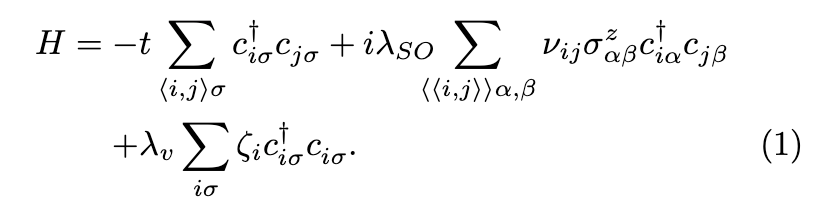

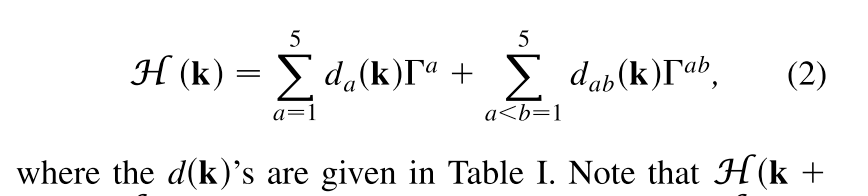

NOTE: KM 原PRL的形式在 Htrig中难于扩展 

### Model

syms t a lambda_SO lambda_v lambda_R  k_x k_y k_z real;
syms q_x q_y;
q_x = k_x/2;
q_y = sqrt(3)/2 *k_y;
Lambda_SO = lambda_SO*cos(k_z);
d_1 = t*(1+2*cos(q_x)*cos(q_y));
d_2 = lambda_v   ;
d_3 = lambda_R*(1-cos(q_x)*cos(q_y));
d_4 = -sqrt(3)*lambda_R*sin(q_x)*sin(q_y);
d_12 = -2*t*cos(q_x)*sin(q_y);
d_15 = 4*Lambda_SO*sin(q_x)*(cos(q_x)-cos(q_y));
d_23 = -lambda_R*(-cos(q_x)*sin(q_y));
d_24 = sqrt(3)*lambda_R*sin(q_x)*cos(q_y);
KaneMele = Htrig(4);
KaneMele = KaneMele+...
    Trig(d_1,gamma_matric(1,'rep','KM'))+...
    Trig(d_2,gamma_matric(2,'rep','KM'))+...
    Trig(d_3,gamma_matric(3,'rep','KM'))+...
    Trig(d_4,gamma_matric(4,'rep','KM'))+...
    ...
    Trig(d_12,gamma_matric(1,2,'rep','KM'))+...
    Trig(d_15,gamma_matric(1,5,'rep','KM'))+...
    Trig(d_23,gamma_matric(2,3,'rep','KM'))+...
    Trig(d_23,gamma_matric(2,3,'rep','KM'))...
;

setting 2th (cos(k_x/2)*cos((3^(1/2)*k_y)/2)) Htrig
setting 1th (1) Htrig


setting 1th (1) Htrig


setting 2th (cos(k_x/2)*cos((3^(1/2)*k_y)/2)) Htrig
setting 1th (1) Htrig


setting 3th (sin(k_x/2)*sin((3^(1/2)*k_y)/2)) Htrig


setting 4th (cos(k_x/2)*sin((3^(1/2)*k_y)/2)) Htrig


setting 5th (cos(k_x/2)*sin(k_x/2)) Htrig
setting 6th (sin(k_x/2)*cos((3^(1/2)*k_y)/2)) Htrig


setting 4th (cos(k_x/2)*sin((3^(1/2)*k_y)/2)) Htrig


setting 4th (cos(k_x/2)*sin((3^(1/2)*k_y)/2)) Htrig


### Analitical

H_KaneMele = simplify(KaneMele.Htrig_sym)

$$H\_KaneMele = \begin{array}{l} \left(\begin{array}{cccc} \lambda_{v}+\sigma_{1}-\sigma_{2} & \sigma_{3} & 0 & \lambda_{R}\,\left(\sigma_{7}-\sigma_{6}+\sigma_{5}-\mathrm{i}\right)\\ \sigma_{4} & \sigma_{2}-\sigma_{1}-\lambda_{v} & -\lambda_{R}\,\left(\sigma_{7}+\sigma_{6}+\sigma_{5}-\mathrm{i}\right) & 0\\ 0 & -\lambda_{R}\,\left(\sigma_{6}-\sigma_{7}+\sigma_{5}+\mathrm{i}\right) & \lambda_{v}-\sigma_{1}+\sigma_{2} & \sigma_{3}\\ -\lambda_{R}\,\left(\sigma_{7}+\sigma_{6}-\sigma_{5}-\mathrm{i}\right) & 0 & \sigma_{4} & \sigma_{1}-\lambda_{v}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\lambda_{\mathrm{SO}}\,\sin\left(k_{x}\right)\\ \sigma_{2}=4\,\lambda_{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\sigma_{9}\\ \sigma_{3}=t\,\left(2\,\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{9}+1-\sigma_{8}\right)\\ \sigma_{4}=t\,\left(2\,\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{9}+1+\sigma_{8}\right)\\ \sigma_{5}=\sqrt{3}\,\sin\left(\frac{k_{x}}{2}\right)\,\sigma_{10}\\ \sigma_{6}=2\,\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{10}\\ \sigma_{7}=\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{9}\,\mathrm{i}\\ \sigma_{8}=2\,\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{10}\,\mathrm{i}\\ \sigma_{9}=\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{10}=\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right) \end{array}$$

% fprintf('When lambda_v = 0\n');
% simplify(eig(subs(H_KaneMele,[lambda_v], 0)))
% fprintf('When k = K \n');
% K_solved = simplify(eig(subs(H_KaneMele,[k_x k_y], 2*pi*sym([1/3,sqrt(3)/3]))))
% K_solved = subs(K_solved,[lambda_v],0)
% K_solved = subs(K_solved,[lambda_SO],0)

### Band

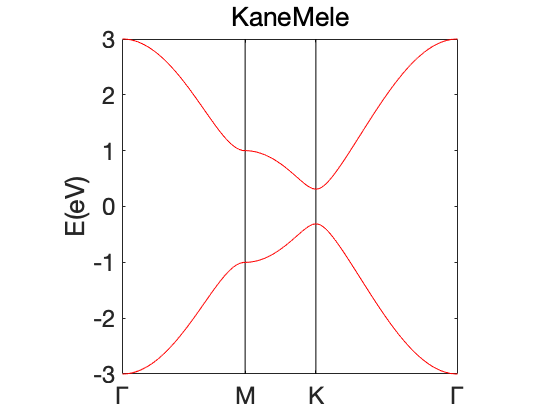

a = 1;t =1;lambda_SO =0.06;lambda_v=0.00;lambda_R = 0;
KaneMele_n  = KaneMele.Subsall();
KaneMele_n = KaneMele_n <'POSCAR_KM_origin';
KaneMele_n = KaneMele_n <'KPOINTS_KM_origin';
EIGENCAR = KaneMele_n.EIGENCAR_gen();
[klist_l,kpoints_l,kpoints_name] = KaneMele_n.kpath_information();
bandplot(EIGENCAR,[-3,3],'KaneMele','r',klist_l,kpoints_l,kpoints_name);

## Descitize in KaneMele

### KaneMele-zigzag

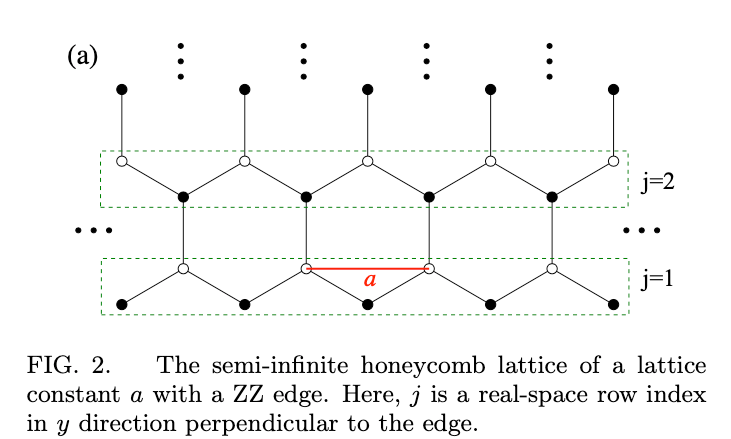

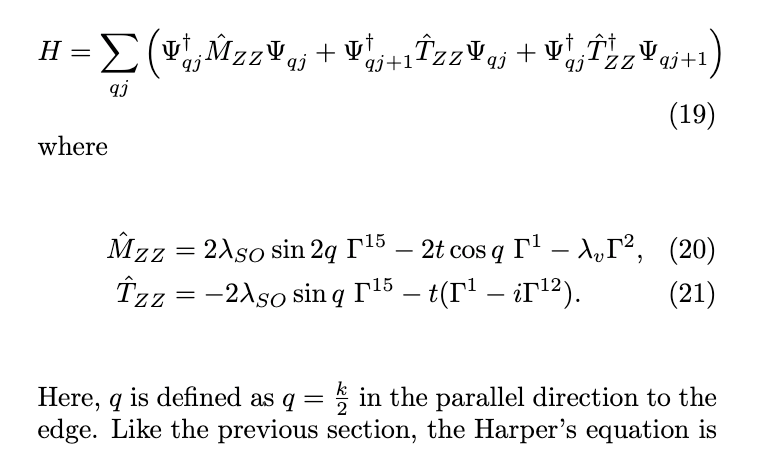

KaneMele.Rm = sym([1/2,sqrt(3)/2,0;-1/2,sqrt(3)/2,0;0 0 2/sqrt(3)])

KaneMele =   Htrig - 属性:

         Kinds: 6
         HcoeL: [4×4×6 sym]
         HnumL: [4×4×6 double]
    HsymL_trig: [1×6 sym]
     Htrig_sym: [4×4 sym]
     Basis_num: 4
            Rm: [3×3 sym]
            Gk: [3×3 sym]

\left(\begin{array}{cccc} \lambda _{v}+4\,\lambda _{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)-4\,\lambda _{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right) & t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,2{}\mathrm{i} & 0 & \sqrt{3}\,\lambda _{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-2\,\lambda _{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-\lambda _{R}\,1{}\mathrm{i}+\lambda _{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{

KaneMele.orbL = sym([    0        0         0.50000000 ;...
    1/3        1/3         0.50000000;...
 0        0         0.50000000 ;...
    1/3        1/3         0.50000000;...
    ]);
KaneMele.Htrig_sym

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \lambda_{v}+\sigma_{7}-\sigma_{2} & \sigma_{5} & 0 & \sigma_{1}-\sigma_{3}-\lambda_{R}\,\mathrm{i}+\sigma_{4}\\ \sigma_{6} & \sigma_{2}-\sigma_{7}-\lambda_{v} & -\sigma_{3}-\sigma_{1}+\lambda_{R}\,\mathrm{i}-\sigma_{4} & 0\\ 0 & -\sigma_{3}-\sigma_{1}-\lambda_{R}\,\mathrm{i}+\sigma_{4} & \lambda_{v}-\sigma_{7}+\sigma_{2} & \sigma_{5}\\ \sigma_{1}-\sigma_{3}+\lambda_{R}\,\mathrm{i}-\sigma_{4} & 0 & \sigma_{6} & \sigma_{7}-\lambda_{v}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{3}\,\lambda_{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{2}=4\,\lambda_{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{3}=2\,\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{4}=\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{5}=t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{6}=t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{7}=4\,\lambda_{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right) \end{array}$$

KaneMele.rotation().Htrig_sym

setting 1th (1) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y)*sin(k_x)) Htrig
setting 7th (cos(k_x)*sin(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \lambda_{v}-\sigma_{4}+\sigma_{3}-\sigma_{2}+\sigma_{1} & \sigma_{5} & 0 & \cos\left(k_{x}\right)\,\sigma_{7}+\cos\left(k_{y}\right)\,\sigma_{8}-\lambda_{R}\,\sin\left(k_{x}\right)-\lambda_{R}\,\sin\left(k_{y}\right)-\lambda_{R}\,\mathrm{i}\\ \sigma_{6} & \sigma_{4}-\lambda_{v}-\sigma_{3}+\sigma_{2}-\sigma_{1} & -\cos\left(k_{x}\right)\,\sigma_{7}-\cos\left(k_{y}\right)\,\sigma_{8}-\lambda_{R}\,\sin\left(k_{x}\right)-\lambda_{R}\,\sin\left(k_{y}\right)+\lambda_{R}\,\mathrm{i} & 0\\ 0 & \cos\left(k_{x}\right)\,\sigma_{8}+\cos\left(k_{y}\right)\,\sigma_{7}-\lambda_{R}\,\sin\left(k_{x}\right)-\lambda_{R}\,\sin\left(k_{y}\right)-\lambda_{R}\,\mathrm{i} & \lambda_{v}+\sigma_{4}-\sigma_{3}+\sigma_{2}-\sigma_{1} & \sigma_{5}\\ -\cos\left(k_{x}\right)\,\sigma_{8}-\cos\left(k_{y}\right)\,\sigma_{7}-\lambda_{R}\,\sin\left(k_{x}\right)-\lambda_{R}\,\sin\left(k_{y}\right)+\lambda_{R}\,\mathrm{i} & 0 & \sigma_{6} & \sigma_{3}-\sigma_{4}-\lambda_{v}-\sigma_{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\lambda_{\mathrm{SO}}\,\cos\left(k_{y}\right)\,\sin\left(k_{x}\right)\\ \sigma_{2}=2\,\lambda_{\mathrm{SO}}\,\cos\left(k_{x}\right)\,\sin\left(k_{y}\right)\\ \sigma_{3}=2\,\lambda_{\mathrm{SO}}\,\sin\left(k_{y}\right)\\ \sigma_{4}=2\,\lambda_{\mathrm{SO}}\,\sin\left(k_{x}\right)\\ \sigma_{5}=t+t\,\cos\left(k_{x}\right)+t\,\cos\left(k_{y}\right)-\sigma_{10}-\sigma_{9}\\ \sigma_{6}=t+t\,\cos\left(k_{x}\right)+t\,\cos\left(k_{y}\right)+\sigma_{10}+\sigma_{9}\\ \sigma_{7}=-\sigma_{11}+\frac{\lambda_{R}\,\mathrm{i}}{2}\\ \sigma_{8}=\sigma_{11}+\frac{\lambda_{R}\,\mathrm{i}}{2}\\ \sigma_{9}=t\,\sin\left(k_{y}\right)\,\mathrm{i}\\ \sigma_{10}=t\,\sin\left(k_{x}\right)\,\mathrm{i}\\ \sigma_{11}=\frac{\sqrt{3}\,\lambda_{R}}{2} \end{array}$$

KaneMele_dy = KaneMele.descritize([0,30,0],'Rotation','auto');

setting 1th (1) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y)*sin(k_x)) Htrig
setting 7th (cos(k_x)*sin(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 1th (Sigma_y_N__N) Htrig
setting 1th (Sigma_y_N__N) Htrig
setting 2th (Sigma_y_1__N) Htrig
setting 1th (Sigma_y_N__N) Htrig
setting 2th (Sigma_y_1__N) Htrig
setting 2th (Sigma_y_1__N) Htrig
setting 2th (Sigma_y_1__N) Htrig


KaneMele_dy.Htrig_sym

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}+\Sigma_{y,N}^{N}\,\left(\lambda_{v}-\sigma_{3}\right) & \sigma_{5} & 0 & \left(\sigma_{6}-\lambda_{R}\,\sin\left(k_{x}\right)-\lambda_{R}\,\mathrm{i}\right)\,\Sigma_{y,N}^{N}+\left(\sigma_{2}-\frac{\lambda_{R}\,\mathrm{i}}{4}\right)\,\Sigma_{y,N}^{1}\\ \sigma_{8} & -\sigma_{1}-\Sigma_{y,N}^{N}\,\left(\lambda_{v}-\sigma_{3}\right) & \left(-\sigma_{6}-\lambda_{R}\,\sin\left(k_{x}\right)+\lambda_{R}\,\mathrm{i}\right)\,\Sigma_{y,N}^{N}+\left(-\sigma_{2}-\sigma_{4}\right)\,\Sigma_{y,N}^{1} & 0\\ 0 & \left(\sigma_{7}-\lambda_{R}\,\sin\left(k_{x}\right)-\lambda_{R}\,\mathrm{i}\right)\,\Sigma_{y,N}^{N}+\left(-\sigma_{2}-\frac{\lambda_{R}\,\mathrm{i}}{4}\right)\,\Sigma_{y,1}^{N} & \Sigma_{y,N}^{N}\,\left(\lambda_{v}+\sigma_{3}\right)-\sigma_{1} & \sigma_{5}\\ \left(-\sigma_{7}-\lambda_{R}\,\sin\left(k_{x}\right)+\lambda_{R}\,\mathrm{i}\right)\,\Sigma_{y,N}^{N}+\left(\sigma_{2}-\sigma_{4}\right)\,\Sigma_{y,1}^{N} & 0 & \sigma_{8} & \sigma_{1}-\Sigma_{y,N}^{N}\,\left(\lambda_{v}+\sigma_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\Sigma_{y,1}^{N}\,\left(\lambda_{\mathrm{SO}}\,\sin\left(k_{x}\right)+\lambda_{\mathrm{SO}}\,\mathrm{i}-\lambda_{\mathrm{SO}}\,\cos\left(k_{x}\right)\,\mathrm{i}\right)\\ \sigma_{2}=\frac{\sqrt{3}\,\lambda_{R}}{4}\\ \sigma_{3}=2\,\lambda_{\mathrm{SO}}\,\sin\left(k_{x}\right)\\ \sigma_{4}=\frac{3\,\lambda_{R}\,\mathrm{i}}{4}\\ \sigma_{5}=\Sigma_{y,N}^{1}\,t+\Sigma_{y,N}^{N}\,\left(t+t\,\cos\left(k_{x}\right)-\sigma_{10}\right)\\ \sigma_{6}=\cos\left(k_{x}\right)\,\left(-\sigma_{9}+\frac{\lambda_{R}\,\mathrm{i}}{2}\right)\\ \sigma_{7}=\cos\left(k_{x}\right)\,\left(\sigma_{9}+\frac{\lambda_{R}\,\mathrm{i}}{2}\right)\\ \sigma_{8}=\Sigma_{y,N}^{N}\,\left(t+t\,\cos\left(k_{x}\right)+\sigma_{10}\right)\\ \sigma_{9}=\frac{\sqrt{3}\,\lambda_{R}}{2}\\ \sigma_{10}=t\,\sin\left(k_{x}\right)\,\mathrm{i} \end{array}$$

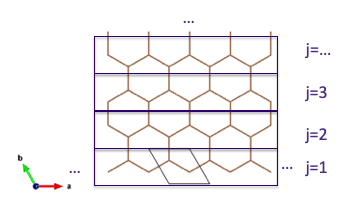

#### KanaMele-slab

a = 1;t =1;lambda_SO =0.06;lambda_v=0.06;
KaneMele_dy = KaneMele_dy<'KPOINTS_slab';

[klist_l,kpoints_l,kpoints_name] = KaneMele_dy.kpath_information();
KaneMele_dy.HcoeL = subs(KaneMele_dy.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
KaneMele_dy = KaneMele_dy.Subsall();

this varible: k_x is the extra parameter


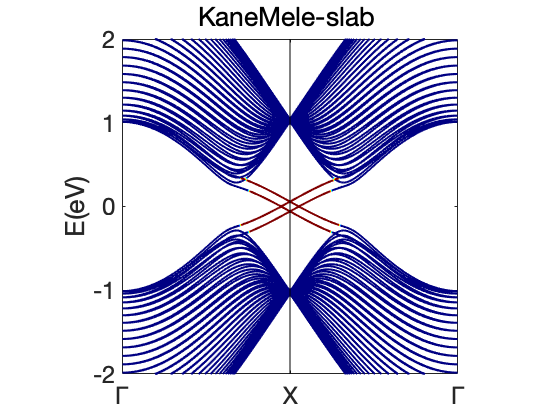

[EIGENCAR_slab,WAVECAR_slab,WEIGHTCAR_slab] = KaneMele_dy.EIGENCAR_gen_slab();
pbandplot(abs(WEIGHTCAR_slab),EIGENCAR_slab,[-2,2],'KaneMele-slab ',@jet,klist_l,kpoints_l,kpoints_name);

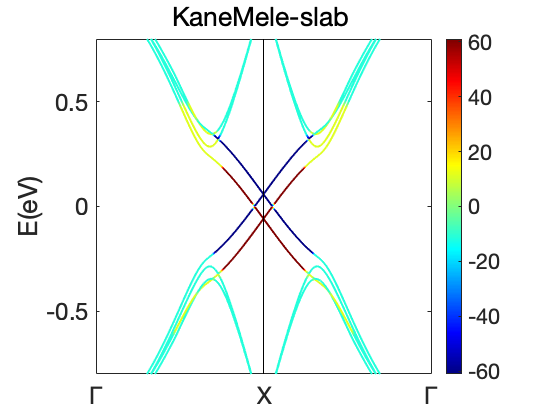

pbandplot(WEIGHTCAR_slab(60-3:60+4,:),EIGENCAR_slab(60-3:60+4,:),[-0.8,0.8],'KaneMele-slab ',@jet,klist_l,kpoints_l,kpoints_name);
colorbar();

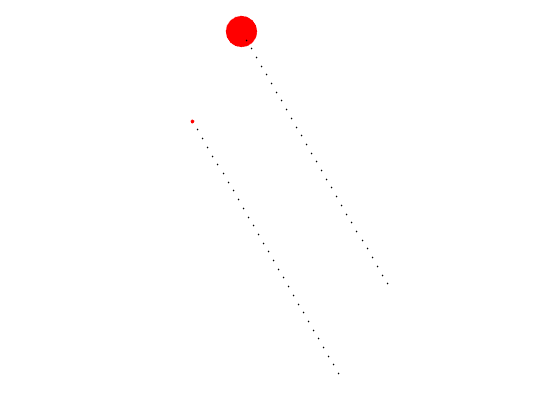

glance mode
   120



ans =          0         0    5.0000         0
    0.1611    0.2983    5.0000         0
         0         0    5.0000         0
    0.1611    0.2983    5.0000         0
   -0.0167    0.0289    5.0000         0
    0.1444    0.3272    5.0000         0
   -0.0167    0.0289    5.0000         0
    0.1444    0.3272    5.0000         0
   -0.0333    0.0577    5.0000         0
    0.1278    0.3560    5.0000         0


WaveFunc = WAVECAR_slab(:,59:60,60);
orb_list= KaneMele_dy.orbL;
figure();
PARCHG_gen(orb_list,WaveFunc)

#### KanaMele-disk

a = 1;t =1;lambda_SO =0.06;lambda_v=0.06;
KaneMele_disk = KaneMele.descritize([30,30,0],'Rotation','auto');

setting 1th (1) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y)*sin(k_x)) Htrig
setting 7th (cos(k_x)*sin(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig
setting 2th (Sigma_x_1__N*Sigma_y_N__N) Htrig
setting 3th (Sigma_y_1__N*Sigma_x_N__N) Htrig
setting 2th (Sigma_x_1__N*Sigma_y_N__N) Htrig
setting 3th (Sigma_y_1__N*Sigma_x_N__N) Htrig
setting 4th (Sigma_x_1__N*Sigma_y_1__N) Htrig
setting 4th (Sigma_x_1__N*Sigma_y_1__N) Htrig


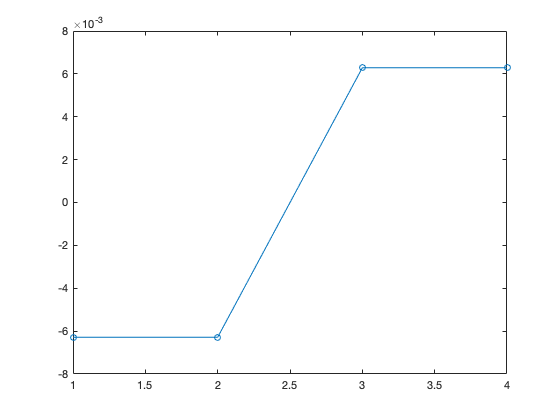

% KaneMele_disk = KaneMele_disk <'KPOINTS_slab';

% [klist_l,kpoints_l,kpoints_name] = KaneMele_dy.kpath_information();
KaneMele_dy.HcoeL = subs(KaneMele_dy.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
KaneMele_disk = KaneMele_disk.Subsall();
[EIGENCAR_disk,WAVECAR_disk,WEIGHTCAR_disk] = KaneMele_disk.EIGENCAR_gen_wire('klist',[0,0,0],'norb',4,'fermi',0+1e-16);
figure();
plot(EIGENCAR_disk,'-o');

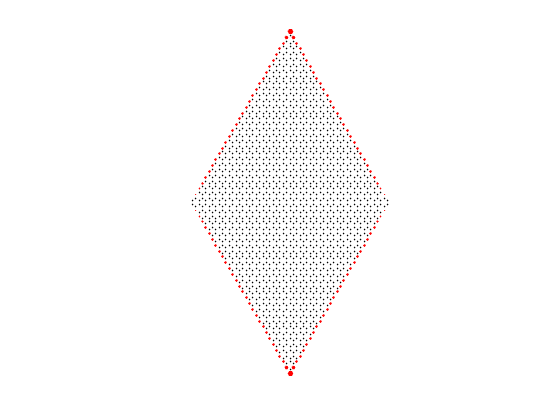

glance mode
        3600



ans =          0         0    5.0000    0.0326
         0    0.0192    5.0000         0
         0         0    5.0000    0.0228
         0    0.0192    5.0000         0
    0.0167    0.0289    5.0000    0.0152
    0.0167    0.0481    5.0000         0
    0.0167    0.0289    5.0000    0.0088
    0.0167    0.0481    5.0000         0
    0.0333    0.0577    5.0000    0.0099
    0.0333    0.0770    5.0000         0


WaveFunc = WAVECAR_disk(:,2:3);
orb_list= KaneMele_disk.orbL;
figure();
copyfile('POSCAR_KM_origin','POSCAR');
PARCHG_gen(orb_list,WaveFunc)

### KanaMele-Add-mag

syms Delta_M phi_1 phi_2 real
H_M =  Delta_M/2 * ([0 0 exp(-1i*phi_1) 0;0 0 0 exp(-1i*phi_2);exp(1i*phi_1) 0 0 0;0 exp(1i*phi_2) 0 0;])

$$H\_M = \left(\begin{array}{cccc} 0 & 0 & \frac{\Delta_{M}\,{\mathrm{e}}^{-\varphi_{1}\,\mathrm{i}}}{2} & 0\\ 0 & 0 & 0 & \frac{\Delta_{M}\,{\mathrm{e}}^{-\varphi_{2}\,\mathrm{i}}}{2}\\ \frac{\Delta_{M}\,{\mathrm{e}}^{\varphi_{1}\,\mathrm{i}}}{2} & 0 & 0 & 0\\ 0 & \frac{\Delta_{M}\,{\mathrm{e}}^{\varphi_{2}\,\mathrm{i}}}{2} & 0 & 0 \end{array}\right)$$

KaneMele_M = KaneMele + H_M

KaneMele_M =   Htrig - 属性:

         Kinds: 6
         HcoeL: [4×4×6 sym]
         HnumL: [4×4×6 double]
    HsymL_trig: [1×6 sym]
     Htrig_sym: [4×4 sym]
     Basis_num: 4
            Rm: [3×3 sym]
            Gk: [3×3 sym]

\left(\begin{array}{cccc} \lambda _{v}+4\,\lambda _{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)-4\,\lambda _{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right) & t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,2{}\mathrm{i} & \frac{\Delta _{M}\,{\mathrm{e}}^{-\phi _{1}\,1{}\mathrm{i}}}{2} & \sqrt{3}\,\lambda _{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-2\,\lambda _{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-\lambda _{R}\,1{}\mathrm{i}+

#### KanaMele-Add-bulk

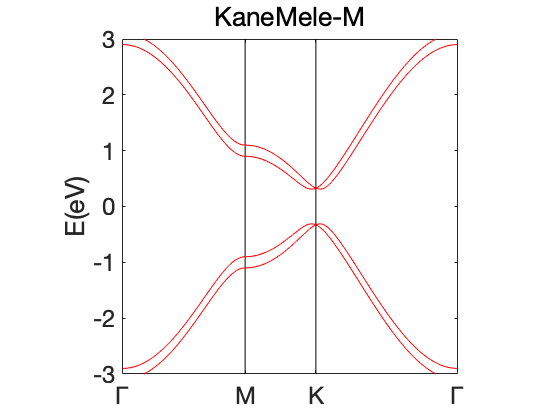

a = 1;t =1;lambda_SO =0.06;Delta_M = 0.2;phi_1 = 0;phi_2 = 0;lambda_v=0.00;lambda_R = 0;
KaneMele_M_n  = KaneMele_M .Subsall();
KaneMele_M_n  = KaneMele_M_n   <'POSCAR_KM_origin';
KaneMele_M_n   = KaneMele_M_n   <'KPOINTS_KM_origin';
EIGENCAR = KaneMele_M_n  .EIGENCAR_gen();
[klist_l,kpoints_l,kpoints_name] = KaneMele_M_n  .kpath_information();
bandplot(EIGENCAR,[-3,3],'KaneMele-M','r',klist_l,kpoints_l,kpoints_name);

#### M-slab;

KaneMele_M_dy = KaneMele_M.descritize([0,30,0],'Rotation','auto');

setting 1th (1) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y)*sin(k_x)) Htrig
setting 7th (cos(k_x)*sin(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 1th (Sigma_y_N__N) Htrig
setting 1th (Sigma_y_N__N) Htrig
setting 2th (Sigma_y_1__N) Htrig
setting 1th (Sigma_y_N__N) Htrig
setting 2th (Sigma_y_1__N) Htrig
setting 2th (Sigma_y_1__N) Htrig
setting 2th (Sigma_y_1__N) Htrig


a = 1;t =1;lambda_SO =0.06;Delta_M = 0.2;phi_1 = 0;phi_2 = 0;lambda_v=0.00;lambda_R = 0;
KaneMele_M_dy = KaneMele_M_dy<'KPOINTS_slab';
[klist_l,kpoints_l,kpoints_name] = KaneMele_M_dy.kpath_information();
KaneMele_M_dy.HcoeL = subs(KaneMele_M_dy.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
KaneMele_M_dy = KaneMele_M_dy.Subsall();

this varible: k_x is the extra parameter


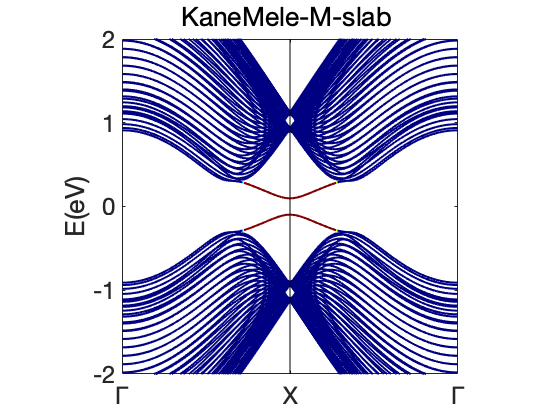

[EIGENCAR_slab,WAVECAR_slab,WEIGHTCAR_slab] = KaneMele_M_dy.EIGENCAR_gen_slab();
pbandplot(abs(WEIGHTCAR_slab),EIGENCAR_slab,[-2,2],'KaneMele-M-slab ',@jet,klist_l,kpoints_l,kpoints_name);

#### M-disk;

a = 1;t =1;lambda_SO =0.06; Delta_M = 0.2; phi_1 = pi+pi/3;phi_2 = 0+pi-pi/3; lambda_v=0.00; lambda_R = 0;
KaneMele_M_disk = KaneMele_M.descritize([31,31,0],'Rotation','auto');

setting 1th (1) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y)*sin(k_x)) Htrig
setting 7th (cos(k_x)*sin(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig
setting 2th (Sigma_x_1__N*Sigma_y_N__N) Htrig
setting 3th (Sigma_y_1__N*Sigma_x_N__N) Htrig
setting 2th (Sigma_x_1__N*Sigma_y_N__N) Htrig
setting 3th (Sigma_y_1__N*Sigma_x_N__N) Htrig
setting 4th (Sigma_x_1__N*Sigma_y_1__N) Htrig
setting 4th (Sigma_x_1__N*Sigma_y_1__N) Htrig


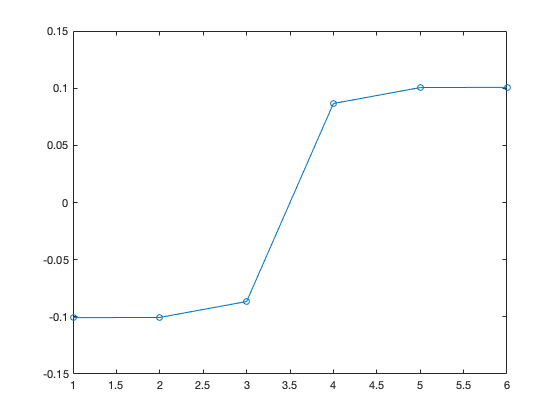

KaneMele_M_disk.HcoeL = subs(KaneMele_M_disk.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
KaneMele_M_disk = KaneMele_M_disk.Subsall();
[EIGENCAR_disk,WAVECAR_disk,WEIGHTCAR_disk] = KaneMele_M_disk.EIGENCAR_gen_wire('klist',[0,0,0],'norb',6,'fermi',0+1e-16);
figure();
plot(EIGENCAR_disk,'-o');

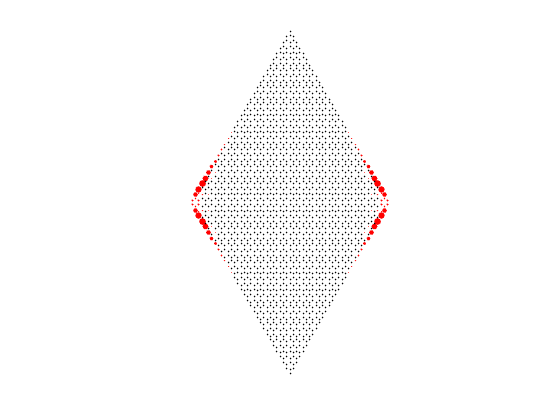

glance mode
        3844



ans =          0         0    5.0000         0
         0    0.0186    5.0000         0
         0         0    5.0000         0
         0    0.0186    5.0000         0
    0.0161    0.0279    5.0000         0
    0.0161    0.0466    5.0000         0
    0.0161    0.0279    5.0000         0
    0.0161    0.0466    5.0000         0
    0.0323    0.0559    5.0000         0
    0.0323    0.0745    5.0000         0


WaveFunc = WAVECAR_disk(:,3:4);
orb_list= KaneMele_M_disk.orbL;
figure();
copyfile('POSCAR_KM_origin','POSCAR');
PARCHG_gen(orb_list,WaveFunc);

#### M-disk-cut


$$\begin{array}{l}
r^2 =\left\lbrack i_1 -0\ldotp 5,i_2 -0\ldotp 5,0\right\rbrack *R_{m\;} ;\;\\
r^{2\;} >\frac{3}{16}
\end{array}$$


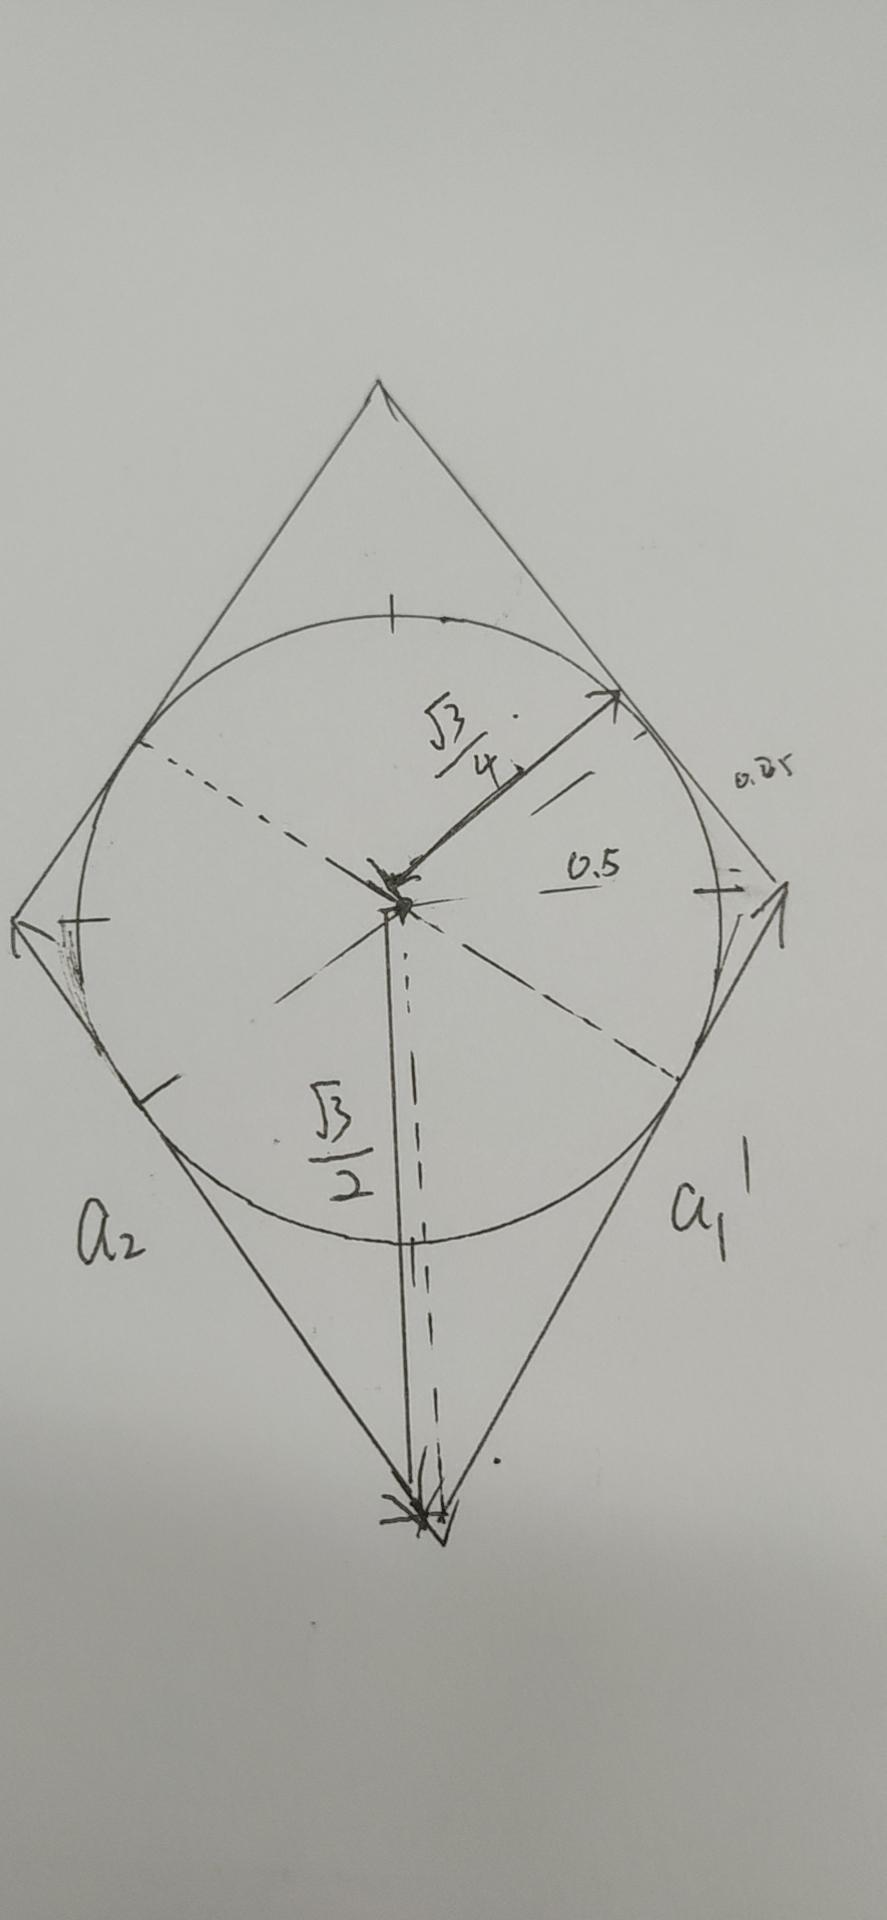

rmfunc = @(i1,i2,i3) (- i2/2 + i1/2)^2 + ((3^(1/2)*(- 1/2 + i1))/2 + (3^(1/2)*(- 1/2 + i2))/2)^2 >= 3/16;
a = 1;t =1;lambda_SO =0.06; Delta_M = 0.2; phi_1 = 0+pi/3;phi_2 = 1/3*pi; lambda_v=0.00; lambda_R = 0;
KaneMele_M.orbL = ... 
sym([    0        0         0.50000000 ;...
         0        0         0.50000000;...
         0        0         0.50000000 ;...
         0        0         0.50000000;...
    ]);
KaneMele_M_disk = KaneMele_M.descritize([51,51,0],'Rotation','auto','rmfunc',rmfunc);

setting 1th (1) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 2th (cos(k_x)) Htrig
setting 3th (cos(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y)*sin(k_x)) Htrig
setting 7th (cos(k_x)*sin(k_y)) Htrig
setting 4th (sin(k_x)) Htrig
setting 5th (sin(k_y)) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig
setting 2th (Sigma_x_1__N*Sigma_y_N__N) Htrig
setting 3th (Sigma_y_1__N*Sigma_x_N__N) Htrig
setting 2th (Sigma_x_1__N*Sigma_y_N__N) Htrig
setting 3th (Sigma_y_1__N*Sigma_x_N__N) Htrig
setting 4th (Sigma_x_1__N*Sigma_y_1__N) Htrig
setting 4th (Sigma_x_1__N*Sigma_y_1__N) Htrig


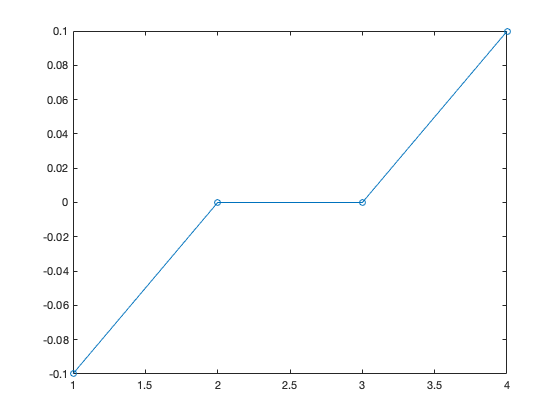

KaneMele_M_disk.HcoeL = subs(KaneMele_M_disk.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
KaneMele_M_disk = KaneMele_M_disk.Subsall();
[EIGENCAR_disk,WAVECAR_disk,WEIGHTCAR_disk] = KaneMele_M_disk.EIGENCAR_gen_wire('klist',[0,0,0],'norb',4,'fermi',0);
figure();
plot(EIGENCAR_disk,'-o');

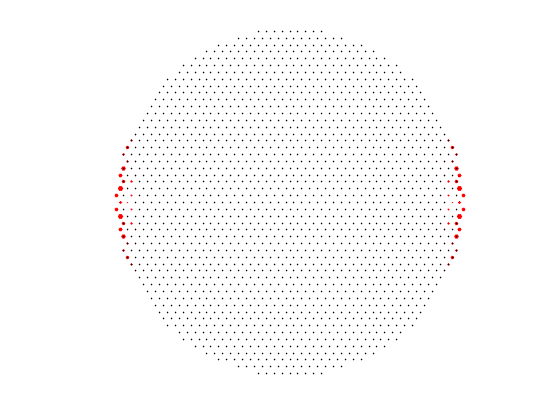

glance mode
        7032



WaveFunc = WAVECAR_disk(:,2:3);
orb_list= KaneMele_M_disk.orbL;
figure();
%copyfile('POSCAR_KM_origin','POSCAR');
PARCHG_gen(orb_list,WaveFunc);

#### M-disk-2

syms Delta_M phi_1 phi_2 real
H_M =  Delta_M/2 * ([0 0 exp(-1i*phi_1) 0;0 0 0 exp(-1i*phi_2);exp(1i*phi_1) 0 0 0;0 exp(1i*phi_2) 0 0;])

$$H\_M = \left(\begin{array}{cccc} 0 & 0 & 0 & \frac{\Delta_{M}\,{\mathrm{e}}^{-\varphi_{1}\,\mathrm{i}}}{2}\\ 0 & 0 & \frac{\Delta_{M}\,{\mathrm{e}}^{-\varphi_{2}\,\mathrm{i}}}{2} & 0\\ 0 & \frac{\Delta_{M}\,{\mathrm{e}}^{\varphi_{1}\,\mathrm{i}}}{2} & 0 & 0\\ \frac{\Delta_{M}\,{\mathrm{e}}^{\varphi_{2}\,\mathrm{i}}}{2} & 0 & 0 & 0 \end{array}\right)$$

KaneMele_M = KaneMele + H_M

KaneMele_M =   Htrig - 属性:

         Kinds: 6
         HcoeL: [4×4×6 sym]
         HnumL: [4×4×6 double]
    HsymL_trig: [1×6 sym]
     Htrig_sym: [4×4 sym]
     Basis_num: 4
            Rm: [3×3 double]
            Gk: [3×3 double]

\left(\begin{array}{cccc} \lambda _{v}+4\,\lambda _{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)-4\,\lambda _{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right) & t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,2{}\mathrm{i} & 0 & \frac{\Delta _{M}\,{\mathrm{e}}^{-\phi _{1}\,1{}\mathrm{i}}}{2}-2\,\lambda _{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)+\sqrt{3}\,\lambda _{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-\lambda _{R}\,1{}\ma

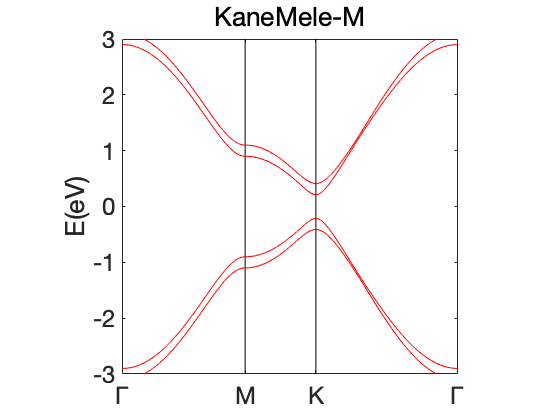

a = 1;t =1;lambda_SO =0.06;Delta_M = 0.2;phi_1 = 0;phi_2 = 0;lambda_v=0.00;lambda_R = 0;
KaneMele_M_n  = KaneMele_M .Subsall();
KaneMele_M_n  = KaneMele_M_n   <'POSCAR_KM_origin';
KaneMele_M_n   = KaneMele_M_n   <'KPOINTS_KM_origin';
EIGENCAR = KaneMele_M_n  .EIGENCAR_gen();
[klist_l,kpoints_l,kpoints_name] = KaneMele_M_n  .kpath_information();
bandplot(EIGENCAR,[-3,3],'KaneMele-M','r',klist_l,kpoints_l,kpoints_name);

KaneMele_M_disk = KaneMele_M.descritize([31,31,0],'Rotation','auto');

setting 1th (1) Htrig
setting 2th (cos(k_x/2)*cos((3^(1/2)*k_y)/2)) Htrig
setting 3th (sin(k_x/2)*sin((3^(1/2)*k_y)/2)) Htrig
setting 4th (cos(k_x/2)*sin((3^(1/2)*k_y)/2)) Htrig
setting 5th (sin(k_x)) Htrig
setting 6th (sin(k_x/2)*cos((3^(1/2)*k_y)/2)) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig
setting 2th (Sigma_x_1__N*Sigma_y_N__N) Htrig
setting 1th (Sigma_x_N__N*Sigma_y_N__N) Htrig


KaneMele_M_disk.HcoeL = subs(KaneMele_M_disk.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
KaneMele_M_disk = KaneMele_M_disk.Subsall();

this varible: k_x is the extra parameter
this varible: k_y is the extra parameter


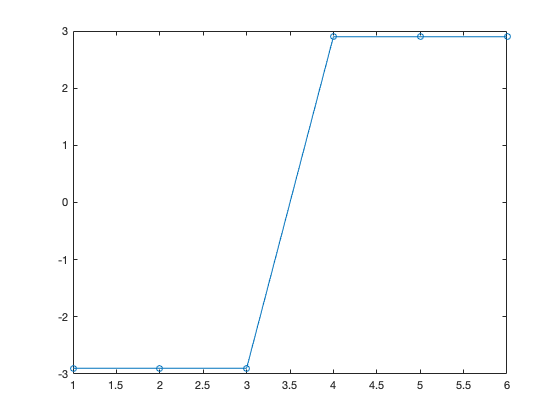

[EIGENCAR_disk,WAVECAR_disk,WEIGHTCAR_disk] = KaneMele_M_disk.EIGENCAR_gen_wire('klist',[0,0,0],'norb',6,'fermi',0+1e-16);
figure();
plot(EIGENCAR_disk,'-o');

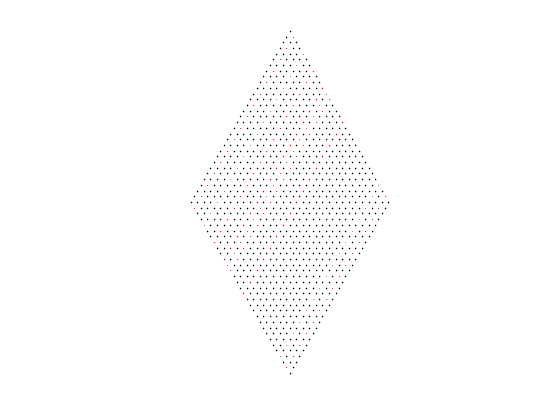

glance mode
        3844



WaveFunc = WAVECAR_disk(:,3:4);
orb_list= KaneMele_M_disk.orbL;
figure();
copyfile('POSCAR_KM_origin','POSCAR');
PARCHG_gen(orb_list,WaveFunc);

### Kane-Mele Armchair

Dont know  how to solve them in only 4 orbital

KaneMele.Rm = sym([sqrt(3),1,0;-1/2,sqrt(3)/2,0;0 0 1/2])

KaneMele =   Htrig - 属性:

         Kinds: 6
         HcoeL: [4×4×6 sym]
         HnumL: [4×4×6 double]
    HsymL_trig: [1×6 sym]
     Htrig_sym: [4×4 sym]
     Basis_num: 4
            Rm: [3×3 sym]
            Gk: [3×3 sym]

\left(\begin{array}{cccc} \lambda _{v}+4\,\lambda _{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right)-4\,\lambda _{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right) & t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,2{}\mathrm{i} & 0 & \sqrt{3}\,\lambda _{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-2\,\lambda _{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-\lambda _{R}\,1{}\mathrm{i}+\lambda _{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{

KaneMele.orbL = [     0.333333333         0.666666667         0.50000000 ;...
    0.666666667         0.333333333         0.50000000;...
    0.333333333         0.666666667         0.50000000 ;...
    0.666666667         0.333333333         0.50000000...
    ];
KaneMele.Htrig_sym

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \lambda_{v}+\sigma_{7}-\sigma_{2} & \sigma_{5} & 0 & \sigma_{1}-\sigma_{3}-\lambda_{R}\,\mathrm{i}+\sigma_{4}\\ \sigma_{6} & \sigma_{2}-\sigma_{7}-\lambda_{v} & -\sigma_{3}-\sigma_{1}+\lambda_{R}\,\mathrm{i}-\sigma_{4} & 0\\ 0 & -\sigma_{3}-\sigma_{1}-\lambda_{R}\,\mathrm{i}+\sigma_{4} & \lambda_{v}-\sigma_{7}+\sigma_{2} & \sigma_{5}\\ \sigma_{1}-\sigma_{3}+\lambda_{R}\,\mathrm{i}-\sigma_{4} & 0 & \sigma_{6} & \sigma_{7}-\lambda_{v}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{3}\,\lambda_{R}\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{2}=4\,\lambda_{\mathrm{SO}}\,\sin\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{3}=2\,\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\\ \sigma_{4}=\lambda_{R}\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{5}=t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)-2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{6}=t+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right)+2\,t\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}\\ \sigma_{7}=4\,\lambda_{\mathrm{SO}}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{k_{x}}{2}\right) \end{array}$$

B = KaneMele.rotation().Htrig_sym

setting 1th (1) Htrig
setting 2th (cos(k_y)) Htrig
setting 3th (cos(k_y/2)*cos((3^(1/2)*k_x)/4)) Htrig
setting 4th (sin(k_y/2)*sin((3^(1/2)*k_x)/4)) Htrig
setting 2th (cos(k_y)) Htrig
setting 3th (cos(k_y/2)*cos((3^(1/2)*k_x)/4)) Htrig
setting 4th (sin(k_y/2)*sin((3^(1/2)*k_x)/4)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y/2)*sin((3^(1/2)*k_x)/4)) Htrig
setting 7th (sin(k_y/2)*cos((3^(1/2)*k_x)/4)) Htrig
setting 6th (cos(k_y/2)*sin((3^(1/2)*k_x)/4)) Htrig
setting 7th (sin(k_y/2)*cos((3^(1/2)*k_x)/4)) Htrig
setting 5th (sin(k_y)) Htrig
setting 6th (cos(k_y/2)*sin((3^(1/2)*k_x)/4)) Htrig
setting 7th (sin(k_y/2)*cos((3^(1/2)*k_x)/4)) Htrig


%KaneMele_dy = KaneMele.descritize([0,30,0],'Rotation','auto');
%KaneMele_dy.Htrig_sym

KaneMele = Htrig(4); 
syms a
KaneMele.Rm = sym(a*[1,0,0;-1/2,sqrt(3)/2,0;0 0 2/sqrt(3)])

KaneMele =   Htrig - 属性:

         Kinds: 1
         HcoeL: [4×4 sym]
         HnumL: [4×4 double]
    HsymL_trig: [1×1 sym]
     Htrig_sym: [4×4 sym]
     Basis_num: 4
            Rm: [3×3 sym]
            Gk: [3×3 sym]

\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)

KaneMele_Rm =KaneMele.Rm

$$KaneMele\_Rm = \left(\begin{array}{ccc} a & 0 & 0\\ -\frac{a}{2} & \frac{\sqrt{3}\,a}{2} & 0\\ 0 & 0 & \frac{2\,\sqrt{3}\,a}{3} \end{array}\right)$$

KaneMele_Gk = KaneMele.Gk

$$KaneMele\_Gk = \left(\begin{array}{ccc} \frac{2\,\pi }{a} & \frac{2\,\pi \,\sqrt{3}}{3\,a} & 0\\ 0 & \frac{4\,\pi \,\sqrt{3}}{3\,a} & 0\\ 0 & 0 & \frac{\pi \,\sqrt{3}}{a} \end{array}\right)$$

inv(KaneMele_Gk/(2*pi)).'

$$ans = \left(\begin{array}{ccc} a & 0 & 0\\ -\frac{a}{2} & \frac{\sqrt{3}\,a}{2} & 0\\ 0 & 0 & \frac{2\,\sqrt{3}\,a}{3} \end{array}\right)$$

syms hat_x hat_y hat_z
syms hat_1 hat_2 hat_3
 KaneMele_Gk*[hat_x;hat_y;hat_z]

$$ans = \left(\begin{array}{c} \frac{2\,\pi \,{\mathrm{hat}}_{x}}{a}+\frac{2\,\pi \,\sqrt{3}\,{\mathrm{hat}}_{y}}{3\,a}\\ \frac{4\,\pi \,\sqrt{3}\,{\mathrm{hat}}_{y}}{3\,a}\\ \frac{\pi \,\sqrt{3}\,{\mathrm{hat}}_{z}}{a} \end{array}\right)$$

## 参考文献

- ﻿10.1103/PhysRevLett.95.146802

- [GrapheneTB(H(k) sin cos)](https://cpb-us-w2.wpmucdn.com/u.osu.edu/dist/3/67057/files/2018/09/graphene_tight-binding_model-1ny95f1.pdf)

- [KaneMeleTB-zigzag](https://journals.aps.org/prb/pdf/10.1103/PhysRevB.88.245115)

- [KaneMeleTB-Armchair](https://arxiv.org/abs/1408.4507)

- [DescritizeTB technique in square lattice](https://journals.aps.org/prb/pdf/10.1103/PhysRevB.48.11851)

- Harper equation 